match=data(1:300,:);
m_ex=table();

%局数差
g_diffe=[];
n=1;
for i=1:300
    if i==300
        break;
    end
    if match{i+1,"set_no"}-match{i,"set_no"}==1
        n=1;
    end
    if match{i,"game_no"}==n
        g_diffe(end+1)=match{i,"p1_games"}-match{i,"p2_games"};
        n=n+1;
    end
end
g_differ=g_diffe';
m_ex=addvars(m_ex,g_differ);


%获胜时小分差
p_diffe=[];
for i=1:300
    if i==300
        p_diffe(end+1)=score2point(match{i,"p1_score"})-score2point(match{i,"p2_score"});
        break;
    end
    if match{i+1,"game_no"}-match{i,"game_no"}~=0 
        p_diffe(end+1)=score2point(match{i,"p1_score"})-score2point(match{i,"p2_score"});
    end
end
p_differ=p_diffe';
m_ex=addvars(m_ex,p_differ);

%绝杀球与失误次数
p1_ac=[];
p2_ac=[];
p1_faul=[];
p2_faul=[];
pa1=0;
pa2=0;
pf1=0;
pf2=0;
for i=1:300
    pa1=pa1+match{i,"p1_ace"};
    pa2=pa2+match{i,"p2_ace"};
    pf1=pf1+match{i,"p1_double_fault"}+match{i,"p1_unf_err"};
    pf2=pf2+match{i,"p2_double_fault"}+match{i,"p2_unf_err"};
    if i==300
        p1_ac(end+1)=pa1;
        p2_ac(end+1)=pa2;
        p1_faul(end+1)=pf1;
        p2_faul(end+1)=pf2;
        break;
    end
    if match{i+1,"game_no"}-match{i,"game_no"} ~=0
        p1_ac(end+1)=pa1;
        p2_ac(end+1)=pa2;
        p1_faul(end+1)=pf1;
        p2_faul(end+1)=pf2;
        pa1=0;
        pa2=0;
        pf1=0;
        pf2=0;
    end
end

p1_ace=p1_ac';
p2_ace=p2_ac';
p1_fault=p1_faul';
p2_fault=p2_faul';

m_ex=addvars(m_ex,p1_ace);
m_ex=addvars(m_ex,p2_ace);
m_ex=addvars(m_ex,p1_fault);
m_ex=addvars(m_ex,p2_fault);

p1_di=[];
p2_di=[];
pd1=0;
pd2=0;
n=0;
for i=1:300
    pd1=pd1+match{i,"p1_distance_run"};
    pd2=pd2+match{i,"p2_distance_run"};
    n=n+1;
    if i==300
        p1_di(end+1)=pd1/n;
        p2_di(end+1)=pd2/n;
        break;
    end
    if match{i+1,"game_no"}-match{i,"game_no"} ~=0
        p1_di(end+1)=pd1/n;
        p2_di(end+1)=pd2/n;
        pd1=0;
        pd2=0;
        n=0;
    end
end

p1_dis=p1_di';
p2_dis=p2_di';
m_ex=addvars(m_ex,p1_dis);
m_ex=addvars(m_ex,p2_dis);

serve=[];
n=1;
for i=1:300
    if i==300
        break;
    end
    if match{i+1,"set_no"}-match{i,"set_no"}==1
        n=1;
    end
    if match{i,"game_no"}==n
        serve(end+1)=match{i,"server"};
        n=n+1;
    end
end

server=serve';
m_ex=addvars(m_ex,server);

writetable(m_ex,'match1.csv')

st=table();
gd_st=m_ex.g_differ-min(m_ex.g_differ);
st=addvars(st,gd_st);

for i=2:8
    m=max(abs(m_ex{:,i}));
    st1=1-abs(m_ex{:,i})/m;
    st=addvars(st,st1);
end

ser_st=[];
for i=1:43
    if m_ex{i,"server"}==1
        ser_st(i)=0;
    end
    if m_ex{i,"server"}==2
        ser_st(i)=1;
    end
end
ser_st=ser_st';
st=addvars(st,ser_st);
for i=1:9
    st{:,i}=st{:,i}/sum(st{:,i}.^2);
end

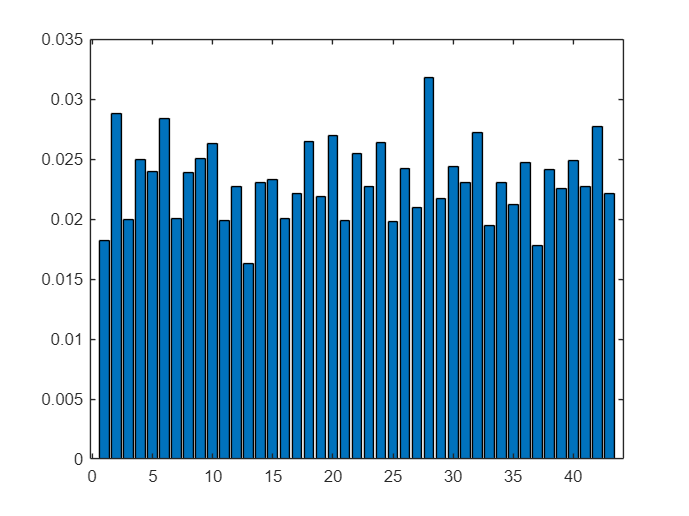

topsisScore=0;
for i=1:9
    positiveIdeal= max(st{:,i});
    negativeIdeal= min(st{:,i});

% 计算对象到正负理想解的距离
    distanceToPositive= sqrt(sum((st{:,i} - positiveIdeal).^2, 2));
    distanceToNegative= sqrt(sum((st{:,i} - negativeIdeal).^2, 2));

% 计算综合得分
    topsisScore =topsisScore+ distanceToNegative ./ (distanceToPositive + distanceToNegative);
end

bar(topsisScore/sum(topsisScore))